# Paraboloidal wave vs spherical wave

% All lengths are in meters.

clear;

% Constants
E0 = 1.0;
lam = 500e-9;
k = 2*pi/lam

k = 1.2566e+07

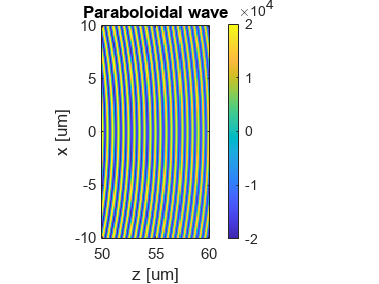


% Visualize E(x,z) of the paraboloidal wave (approximation).
% Create a 2D grid for (x,z)
dx = 0.1e-6;  % 0.1 um; typically 1/100 of the area to be sampled, in order of magnitude
x = -10e-6:dx:10e-6;  nx = length(x);
z = 50e-6:dx:60e-6;  nz = length(z);

[gx, gz] = ndgrid(x, z);

% Create a 2D array for E(x,z)
% Here, we use the complex representation to build the array and take its real part when visualizing the field.
E = E0 ./ gz .* exp(1i * k./(2*gz) .* (gx.^2 + 0.^2)) .* exp(1i * k * gz);

% Plotting Paraboloidal wave
figure;
imagesc(z*1e6, x*1e6, real(E));
colorbar;
ax = gca;
ax.YDir = "normal";
ax.DataAspectRatio = [1 1 1];
ax.XLabel.String = "z [um]";
ax.YLabel.String = "x [um]";
ax.Title.String = "Paraboloidal wave";

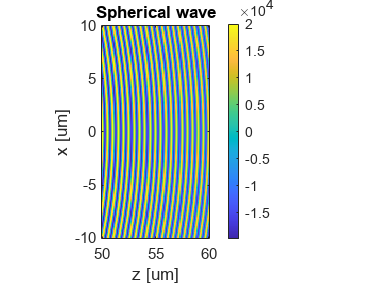


% Visualize E(x,z) of the original spherical wave.
r = sqrt(gx.^2 + 0.^2 + gz.^2);
Esp = E0 ./ r .* exp(1i * k * r);

% Plotting Spherical wave
figure;
imagesc(z*1e6, x*1e6, real(Esp));
colorbar;
ax = gca;
ax.YDir = "normal";
ax.DataAspectRatio = [1 1 1];
ax.XLabel.String = "z [um]";
ax.YLabel.String = "x [um]";
ax.Title.String = "Spherical wave";


% Quantify the difference (relative to the original wave).
diff_ratio = mean2(abs(E-Esp).^2) / mean2(abs(Esp).^2)

diff_ratio = 0.0012

fresnel_check = 0.0400

k = 1.2566e+07

ans =    201   101


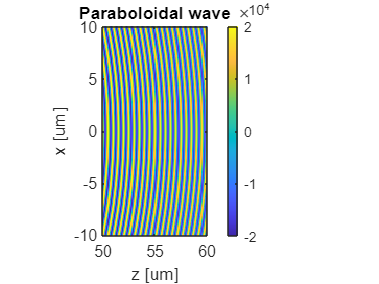

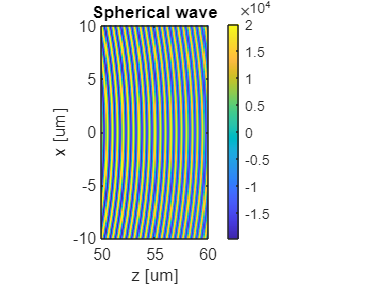

ans = 0.0012


% Check the validity of the Fresnel approximation.
% The result should be much smaller than 1.
xMax = max(x);
zMin = min(z);
fresnel_check = xMax^4 / (4 * lam * zMin^3)

This $\frac{\rho^4}{4 \lambda z^3}$ should be much smaller than 1. 